# 5.2.2 字符向量

c1 = ['A','p','p','l','e']  % 行字符向量

c1 = 'Apple'

c2 = ['x';'y';'z']  % 列字符向量

c2 = 3×1 char 数组
    'x'
    'y'
    'z'

c2'  % 对c2转置就能得到一个行字符向量

ans = 'xyz'

c = 'aAbB';
double(c)

ans =     97    65    98    66


d = 65:90

d =     65    66    67    68    69    70    71    72    73    74    75    76    77    78    79    80    81    82    83    84    85    86    87    88    89    90


char(d)

ans = 'ABCDEFGHIJKLMNOPQRSTUVWXYZ'

小技巧：

'A':'Z'

ans = 'ABCDEFGHIJKLMNOPQRSTUVWXYZ'

'A':2:'Z'

ans = 'ACEGIKMOQSUWY'

'0':'9'

ans = '0123456789'

'Z':-1:'A'

ans = 'ZYXWVUTSRQPONMLKJIHGFEDCBA'

'0':'z'

ans = '0123456789:;<=>?@ABCDEFGHIJKLMNOPQRSTUVWXYZ[\]^_`abcdefghijklmnopqrstuvwxyz'

double('0':'z')

ans =     48    49    50    51    52    53    54    55    56    57    58    59    60    61    62    63    64    65    66    67    68    69    70    71    72    73    74    75    76    77    78    79    80    81    82    83    84    85    86    87    88    89    90    91    92    93    94    95    96    97


d = [65;66;67];  % 列向量
char(d)

ans = 3×1 char 数组
    'A'
    'B'
    'C'

c1 = 'abc';
c2 = 'ABC';
c1 - c2

ans =     32    32    32


c2 + 32

ans =     97    98    99


char(c2 + 32)

ans = 'abc'

c1

c1 = 'abc'

c3 = ['a';'b'];
c3

c3 = 2×1 char 数组
    'a'
    'b'

c1 - c3  % 算术运算的兼容模式

ans =      0     1     2
    -1     0     1


c1 > c3  % 也可以进行关系运算

ans = 2×3 logical 数组
   0   1   1
   0   0   1



% c1 = 'abc';
% c2 = 'ABCD';
% c1 - c2


c1 = '我喜欢你，真的不骗你';
c1(2:3)  % 引用c1中2、3位置上的字符

ans = '喜欢'

c1(end-4:end)  % 引用c1中最后五个字符

ans = '真的不骗你'

c1(4) = '她';  % 修改c1的第四个位置的字符
c1

c1 = '我喜欢她，真的不骗你'

c1(4:end-1) = [];  % 删除指定位置的字符
c1

c1 = '我喜欢你'

c1(2:3) = '想';  % 右侧可以是单个字符
c1 

c1 = '我想想你'

c1 = c1(end:-1:1); % 颠倒字符向量的顺序
c1

c1 = '你想想我'

c1(2:3) =  '不爱'; 
c1

c1 = '你不爱我'

% c1(2:3) = '不喜欢'; 
% c1


c1 = 'Good ';
c2 = 'Morning';
% 横向(水平)拼接字符向量
[c1,c2] 

ans = 'Good Morning'

cat(2,c1,c2)  % dim=2表示沿着列方向拼接

ans = 'Good Morning'

horzcat(c1,c2)

ans = 'Good Morning'

% 以上三种方法都可以哦
c3 = 'abc';
repmat(c3,1,3)  % 重复堆叠1×3次

ans = 'abcabcabc'

% repmat(c3,2,3)
c4 = 'abc';
repelem(c4, 3) % 重复字符向量中的元素3次

ans = 'aaabbbccc'

c5 = 'efcd0Agba'; 
sort(c5)  % 按照Unicode数值大小排序

ans = '0Aabcdefg'

sort(c5,'descend')

ans = 'gfedcbaA0'

c6 = '1':'9';  % '123456789'
% 对字符向量左右翻转
flip(c6)

ans = '987654321'

fliplr(c6)

ans = '987654321'

c6(end:-1:1)

ans = '987654321'

% 以上三种方法都可以哦

% c1 = 'I'm Li Hua.'
c2 = 'I''m Li Hua.'

c2 = 'I'm Li Hua.'

c3 = 'a''''b'

c3 = 'a''b'

c = '春眠不觉晓，处处闻啼鸟。';
char(10)

ans =     '
     '

c1 = c(1:6)

c1 = '春眠不觉晓，'

c2 = c(7:end)

c2 = '处处闻啼鸟。'

c_new = [c1, char(10), c2]

c_new =     '春眠不觉晓，
     处处闻啼鸟。'

c_new = [c1, newline, c2]

c_new =     '春眠不觉晓，
     处处闻啼鸟。'

c = 'abcdefg';
numel(c)

ans = 7

length(c)

ans = 7

size(c)

ans =      1     7


c1 = 'pool';
c2 = 'moon';
c1 == c2

ans = 1×4 logical 数组
   0   1   1   0


c3 = '你说你喜欢我，希望你没说谎';
ind = c3 == '你'

ind = 1×13 logical 数组
   1   0   1   0   0   0   0   0   0   1   0   0   0


num = sum(ind) % c3中'你'出现的次数

num = 3

c4 = 'abc';
c5 = ['a';'b';'c'];  % 列字符向量
c4 == c5

ans = 3×3 logical 数组
   1   0   0
   0   1   0
   0   0   1


% c6 = 'abc';
% c7 = 'abcd';  
% c6 == c7


c1 = 'pool';
c2 = 'moon';
strcmp(c1,c2)

ans = logical
   0

c3 = 'abc';
c4 = 'abcd';  
strcmp(c3,c4)

ans = logical
   0

c5 = 'abc';
c6 = ['a';'b';'c'];  % 列字符向量
strcmp(c5,c6) % 比较时会区分字符向量的方向

ans = logical
   0

c7 = 'apple';
c8 = 'Apple';  
strcmp(c7,c8) % 比较时会区分大小写字母

ans = logical
   0

函数名	功能

strcmp	比较字符向量是否相同（区分大小写）

strcmpi	比较字符向量是否相同（不区分大小写）

strncmp	比较字符向量的前 n 个字符是否相同（区分大小写）

strncmpi	比较字符向量的前 n 个字符是否相同（不区分大小写）

% 比较整个字符，区分大小写
strcmp('abc','Abc')

ans = logical
   0

% 比较整个字符，不区分大小写
strcmpi('abc','Abc')

ans = logical
   1

% 比较前3个字符，区分大小写
strncmp('wxYz','wxy012',3)

ans = logical
   0

% 比较前3个字符，不区分大小写
strncmpi('wxYz','wxy012',3)

ans = logical
   1

c = '我会Matlab、Python、Spss等软件！';
% 97至122代表小写字母 'a' 至 'z'
% 65至90代表大写字母 'A' 至 'Z'
d = double(c)

d =        25105       20250          77          97         116         108          97          98       12289          80         121         116         104         111         110       12289          83         112         115         115       31561       36719       20214       65281


% 筛选出d中数值位于97和122之间的元素
ind = d >= 97 & d <= 122

ind = 1×24 logical 数组
   0   0   0   1   1   1   1   1   0   0   1   1   1   1   1   0   0   1   1   1   0   0   0   0


d(ind)

ans =     97   116   108    97    98   121   116   104   111   110   112   115   115


d(ind) = d(ind) - 32 % Unicode编码相差32

d =        25105       20250          77          65          84          76          65          66       12289          80          89          84          72          79          78       12289          83          80          83          83       31561       36719       20214       65281


cc = char(d)  % 转换回字符向量

cc = '我会MATLAB、PYTHON、SPSS等软件！'

如果你熟练的话，可以不用double转换，直接使用字符向量进行运算：

c

c = '我会Matlab、Python、Spss等软件！'

ind = c >= 97 & c <= 122

ind = 1×24 logical 数组
   0   0   0   1   1   1   1   1   0   0   1   1   1   1   1   0   0   1   1   1   0   0   0   0


% c(ind)
% c(ind)-32
% char(c(ind)-32)
c(ind) = char(c(ind)-32)

c = '我会MATLAB、PYTHON、SPSS等软件！'

这种方法直接在字符向量上操作，避免了将字符先转换为它们的ASCII编码（使用double函数），然后再进行运算的步骤。

这两行代码充分展示了MATLAB处理字符数据的灵活性。

c = '我会Matlab、Python、Spss等软件！';
upper(c)

ans = '我会MATLAB、PYTHON、SPSS等软件！'

lower(c)

ans = '我会matlab、python、spss等软件！'

（2）实现内置函数strcmp的功能（仅考虑比较的两个文本都是字符向量的类型）

% 要比较的两个字符向量分别为c1和c2
c1 = 'abc';
c2 = 'Abcd';  
% c2 = ['a';'b';'c'];  % 列字符向量
% c2 = 'abc';
% c2 = 'abcd';
% size(c1) == size(c2)
 % all(size(c1) == size(c2))
 % c1 == c2
% flag = all(size(c1) == size(c2)) && ...
%        all(c1 == c2) 
% all(c1 == c2)  % 实际上这一行代码是上一行中没写完的部分
% flag是标志变量，为逻辑值1则代表c1和c2完全相同，为逻辑值0则说明不同
flag = all(size(c1) == size(c2)) && ...  三个点 ... 用来表示行的延续
       all(c1 == c2)  % 实际上这一行代码是上一行中没写完的部分

flag = logical
   0

数字和…中间请用空格隔开

x = 1 - 1/2 + 1/3 - 1/4 + 1/5 ...
      - 1/6 + 1/7 - 1/8 + 1/9

x = 0.7456

x = 1 - 1/2 + 1/3 - 1/4 + 1/5 - 1/6 + 1/7 - 1/8 + 1/9

x = 0.7456

`如果行末尾之前存在三个或更多个点，则` MATLAB `会忽略该行的其余部分而直接延续到下一行。这相当于将当前行第一次出现的三个点之后的任何内容作为注释。`

y = 1:100;
ind = mod(y,3) == 0 & ... 3的倍数
      mod(y,5) == 0 & ... 5的倍数
      mod(y,6) ~= 0;  % 不是6的倍数
y(ind)

ans =     15    45    75


% a = 3 + 6 ...
%     6
a = 3 + ...
    66

a = 69

错误的写法：

% y = 1 +...
%     2 +...
%   % 3 +...
%     4

正确的写法：

y = 1 +...
    2 +...
... 3 +...
    4

y = 7

统计字符向量中元音字母出现的频率（元音是指aeiouAEIOU）

c = 'I wish you and your family good health, and all the best.';
% numel(c)  % 57
ind = ismember(c,'aeiouAEIOU')

ind = 1×57 logical 数组
   1   0   0   1   0   0   0   0   1   1   0   1   0   0   0   0   1   1   0   0   0   1   0   1   0   0   0   0   1   1   0   0   0   1   1   0   0   0   0   0   1   0   0   0   1   0   0   0   0   0


num = sum(ind)  % 元音字母出现的次数

num = 17

pl = num / numel(c)  % 计算频率

pl = 0.2982

思考：不使用ismember函数能否算出num?

（1）循环

c = 'I wish you and your family good health, and all the best.';
yy = 'aeiouAEIOU';  % 元音字母
n = numel(c);
num = 0;
for ii = 1:n
    if any(c(ii) == yy)
        num = num + 1;
    end
end
num

num = 17

pl = num / n

pl = 0.2982

c = [5 3 6];
for ii = c
    ii
end

ii = 5

ii = 3

ii = 6

c = 'I wish you and your family good health, and all the best.';
yy = 'aeiouAEIOU';  % 元音字母
n = numel(c);
num = 0;
for ii = c
    if any(ii == yy)
        num = num + 1;
    end
end
pl = num / n

pl = 0.2982

（2）关系运算

c = 'I wish you and your family good health, and all the best.';
yy = 'aeiouAEIOU';  % 元音字母
yy'

ans = 10×1 char 数组
    'a'
    'e'
    'i'
    'o'
    'u'
    'A'
    'E'
    'I'
    'O'
    'U'

c == yy'

ans = 10×57 logical 数组
   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   1   0   0   0   1   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0 

any(c == yy')

ans = 1×57 logical 数组
   1   0   0   1   0   0   0   0   1   1   0   1   0   0   0   0   1   1   0   0   0   1   0   1   0   0   0   0   1   1   0   0   0   1   1   0   0   0   0   0   1   0   0   0   1   0   0   0   0   0


% ind = ismember(c,'aeiouAEIOU')
num = sum(any(c == yy'))

num = 17

pl = num / numel(c)

pl = 0.2982

`凯撒密码`

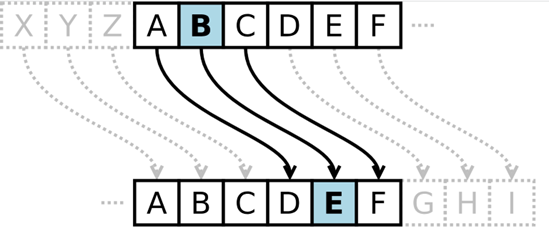

% 凯撒密码加密程序
% 输入：明文字符向量 c
% 偏移量设置为 +3
c = 'Retreat to the countryside tomorrow morning.';
% 定义映射关系
x = ['A':'Z','a':'z']; 
y = ['D':'Z','A':'C','d':'z','a':'c']; 
% 初始化加密后的字符向量为原始字符向量
cc = c; % 创建加密后的字符向量，初始值与明文相同
n = numel(c); % 获取明文字符向量c的长度
% 遍历明文字符向量中的每一个字符
for ii = 1:n
    % 检查当前字符是否为字母，并进行加密替换
    ind = find(cc(ii) == x, 1); % 查找当前字符在x中的位置
    if ~isempty(ind) % 如果当前字符是字母
        cc(ii) = y(ind); % 则用映射后的字母进行替换
    end
end

% 输出加密后的字符向量
disp(cc)

Uhwuhdw wr wkh frxqwubvlgh wrpruurz pruqlqj.


后续章节还会学习文本的替换功能，例如strrep函数和replace函数

c = 'Retreat to the countryside tomorrow morning.';
% 定义映射关系
x = ['A':'Z','a':'z']; 
y = ['D':'Z','A':'C','d':'z','a':'c']; 
cc = c;
[ind,d] = ismember(c,x)

ind = 1×44 logical 数组
   1   1   1   1   1   1   1   0   1   1   0   1   1   1   0   1   1   1   1   1   1   1   1   1   1   1   0   1   1   1   1   1   1   1   1   0   1   1   1   1   1   1   1   0


d =     18    31    46    44    31    27    46     0    46    41     0    46    34    31     0    29    41    47    40    46    44    51    45    35    30    31     0    46    41    39    41    44    44    41    49     0    39    41    44    40    35    40    33     0


ismember(c, x)函数检查c中的每个字符是否在x中出现。ind是一个逻辑数组，表示c中的每个字符是否是字母。d是一个数值数组，表示c中的字符在x中的位置索引。

cc(ind) = y(d(ind));  % 将cc中的字母替换为y中对应的加密后的字母。
% 输出加密后的字符向量
disp(cc)

Uhwuhdw wr wkh frxqwubvlgh wrpruurz pruqlqj.


cc

cc = 'Uhwuhdw wr wkh frxqwubvlgh wrpruurz pruqlqj.'

上面的两种方法虽然可行，但是通用性较差，如果换了一个偏移量就得重新生成映射关系 

以offset  = 3为例

1-23没问题  变成了4-26

24 25 26 需要变成 1 2 3

 怎么处理？

1-26  -- >  4-26 1 2 3

i = 1:26;
mod(i+3,26)

ans =      4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25     0     1     2     3


mod(i-1+3,26)+1

ans =      4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26     1     2     3


i = 'A':'Z'

i = 'ABCDEFGHIJKLMNOPQRSTUVWXYZ'

char(mod(i-'A'+3,26)+'A')

ans = 'DEFGHIJKLMNOPQRSTUVWXYZABC'

c = 'Retreat to the countryside tomorrow morning.';
% c = char([97:122,65:90])
cc = c; % 初始化加密后的字符向量等于c
offset = 3; % 定义偏移量
for i = 1:numel(c)  % 遍历字符向量c的每个字符
        if c(i) >= 'A' && c(i) <= 'Z'  % 判断当前字符是否为大写字母
            cc(i) = char(mod(c(i) - 'A' + offset, 26) + 'A');
        elseif c(i) >= 'a' && c(i) <= 'z'  % 判断当前字符是否为小写字母
            cc(i) = char(mod(c(i) - 'a' + offset, 26) + 'a');
        end   % 这里不需要else，对于非字母字符，它们保持不变
end
% 输出加密后的字符向量
disp(cc)

Uhwuhdw wr wkh frxqwubvlgh wrpruurz pruqlqj.


            如果字符是大写字母（在'A'到'Z'之间），我们将其转换为一个0到25的数字（通过减去'A'），然后加上偏移量offset，接着使用mod函数进行模26运算。模26运算确保字母在超过'Z'后会回绕到字母表的开头。之后再加上'A'并将数字转回Unicode编码对应的大写字母。

`字符`'C'`为例，`'C' - 'A' + 3`等于5，`mod(5,26)`等于5，然后用5加上`'A'`并转换回相应字符后得到`'F'`。`

`以字符`'Y'`为例，`'Y' - 'A' + 3`等于`27`，`mod(27,26)`等于`1`，然后用`1`加上`'A'`并转换回相应字符后得到`'B'`。`

大家可以试试，将偏移量改成-3后结果是什么？

offset = -5;
i = 'A':'Z'

i = 'ABCDEFGHIJKLMNOPQRSTUVWXYZ'

char(mod(i-'A'+offset,26)+'A')

ans = 'VWXYZABCDEFGHIJKLMNOPQRSTU'

mod(-1,26)

ans = 25

mod(-2,26)

ans = 24

`编写程序将用户输入的十进制正整数转换为对应的二进制字符向量。`

n = 60658;  % 需要转换的十进制正整数
c = '';  % 初始化二进制数为空的字符向量
quotient = n;  % 初始化商等于n
while quotient > 0
    remainder = mod(quotient, 2);  % 除以2的余数
    quotient = fix(quotient / 2);  % 更新商
    c = [num2str(remainder), c];   % 更新c  
end
disp(c)

1110110011110010


**num2str**`函数:``将数字转换成字符的形式`

num2str(520)

ans = '520'

% format short
% x = pi
num2str(pi)

ans = '3.1416'

num2str(pi,3)  % 指定有效数字的最大位数为3

ans = '3.14'

num2str(pi,10)  % 指定有效数字的最大位数为10

ans = '3.141592654'

注意，有效位数取得太长结果可能不精确

num2str(pi,40)

ans = '3.141592653589793115997963468544185161591'

查到的真实值：3.141592653589793238462643383279... 

拓展：如果你有符号计算工具箱的话，可以使用下面的代码计算pi的精确值：

 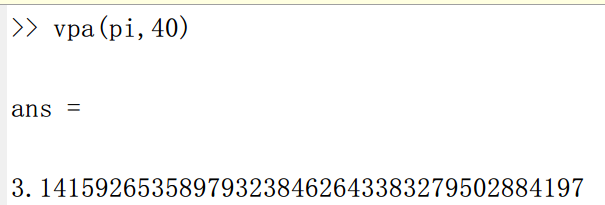

num2str(1:10)  % 将行向量转换为对应的字符向量

ans = '1   2   3   4   5   6   7   8   9  10'

num2str([1;2;3])  % 将列向量进行转换

ans = 3×1 char 数组
    '1'
    '2'
    '3'

x = [3 4;
     1 10;
     7 8];
num2str(x)  % 将数值矩阵转换为对应的字符矩阵

ans = 3×5 char 数组
    '3   4'
    '1  10'
    '7   8'

num2str([3;51;100])

ans = 3×3 char 数组
    '  3'
    ' 51'
    '100'

**dec2base**`函数``可以将十进制`(decimalism)`整数转换为其` n `进制表示形式：`

D = 38;
dec2base(D,2)  % 转换成二进制

ans = '100110'

等价于使用函数dec2bin

dec2bin(D)

ans = '100110'

和MATLAB内置函数比较

n = 999999;  % 需要转换的十进制正整数
c = '';  % 初始化二进制数为空的字符向量
quotient = n;  % 初始化商等于n
while quotient > 0
    remainder = mod(quotient, 2);  % 除以2的余数
    quotient = fix(quotient / 2);  % 更新商
    c = [num2str(remainder), c];   % 更新c  
end
c

c = '11110100001000111111'

strcmp(dec2base(n,2),c)

ans = logical
   1

strcmp(dec2bin(n),c)

ans = logical
   1

配套的讲解视频可在b站免费观看：

《MATLAB教程新手入门篇（数学建模清风主讲，适合零基础同学观看）》

[https://www.bilibili.com/video/BV1dN4y1Q7Kt/](https://www.bilibili.com/video/BV1dN4y1Q7Kt/)